# Identificazione in frequenza in anello chiuso, con segnale eccitante sulla coppia

Motivazione:

- L'identificazione in anello aperto non consente di limitare l'andamento del sistema, causando possibili urti o il raggiungimento dei limiti del sistema

Obiettivi:

- analizzare le differenza fra la stima in anello aperto e anello chiuso al variare delle frequenza

- analizzare l'effetto del transitorio

## Sistema simulato

uso un sistena motore-trasmissione elastica-carico

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi
robot=ElasticRoboticSystem('spong1');
robot.show;

This system has 2 outputs:
- position_1
- velocity_1
This system has 1 inputs:
- torque_1, with maximum limit = 62.000000


Tc = robot.getSamplingPeriod;
robot.initialize;

## Identificazione close-loop / open-loop

Il segnale eccitante può essere fornito in ingresso al sistema controllato in open-loop, dove non avremmo nessun controllo sul sistema che potrebbe derivare dal punto di equilibrio desiderato.

E' possibile eccitare il sistema anche in close-loop, inserendo il segnale eccitante attraverso il setpoint o sommandolo all'uscita del controllore.

Consideriamo il secondo caso. 

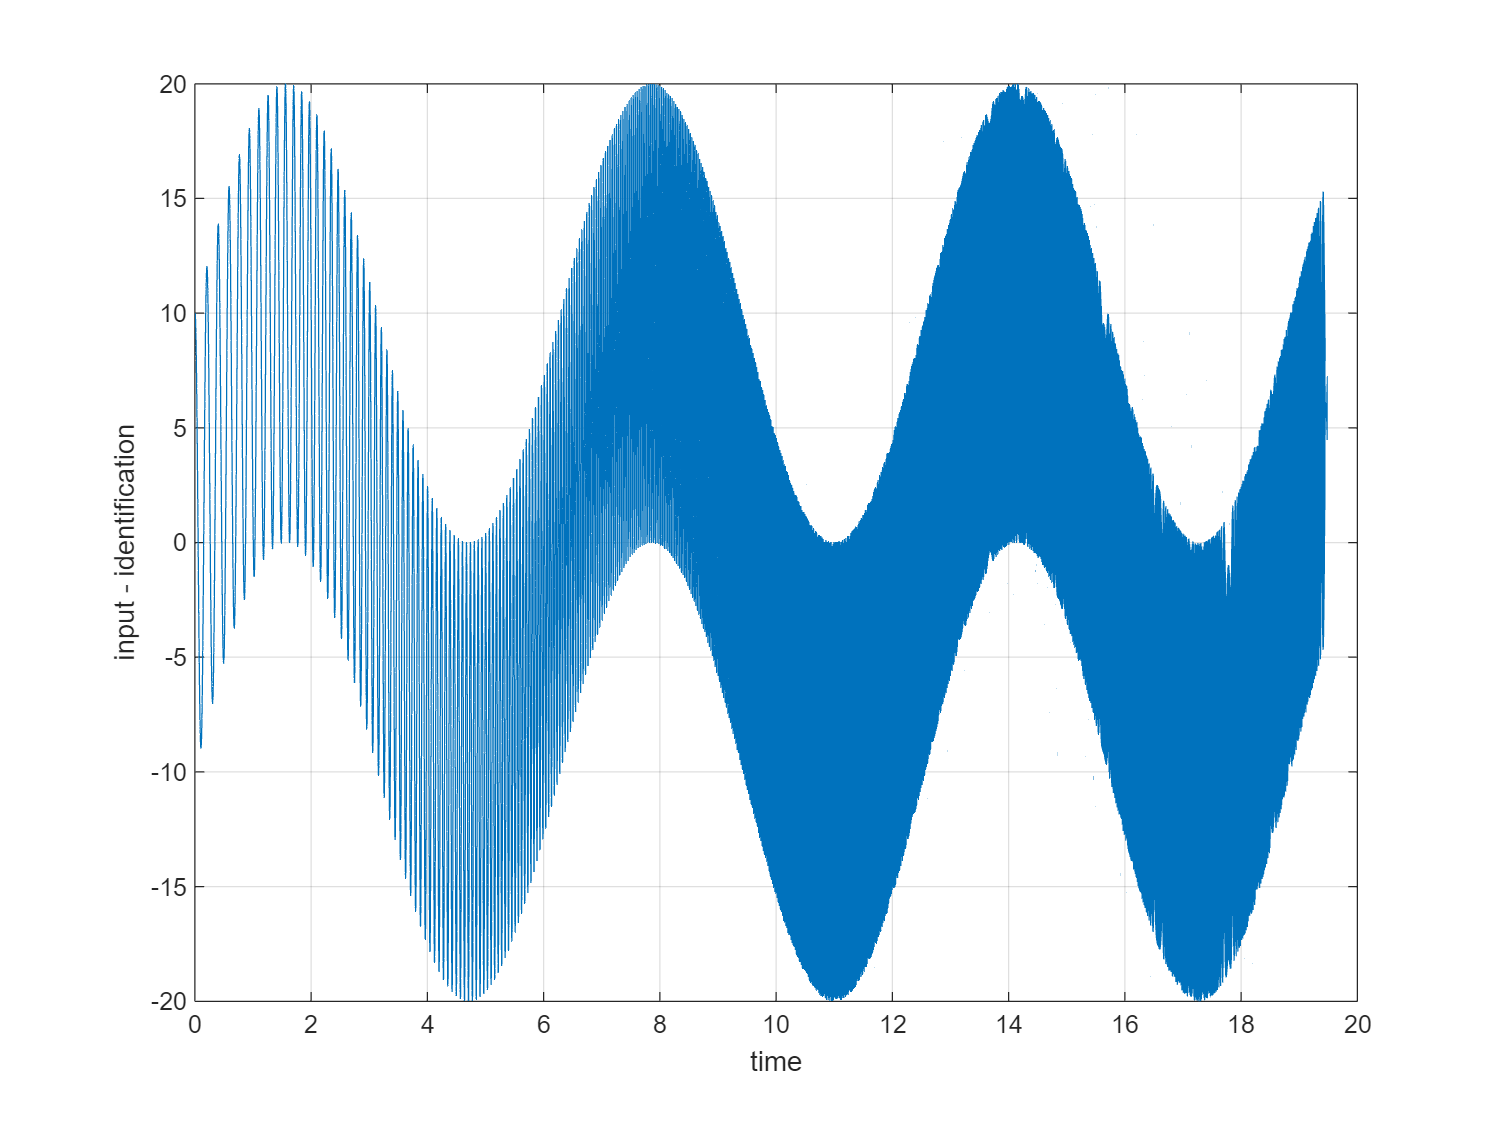

omega_portante=1;
ampiezza_portante=10;
T_portante=2*pi/omega_portante;
t=(0:Tc:(3.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);
w0=omega_portante*30; %rad/s
w1=pi/Tc; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=10;
control_action_ffw=portante+ control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action_ffw)
xlabel('time')
ylabel('input - identification')
grid on

Considero le funzioni di trasferimento:

- fra coppia $U(s)$ e velocità del sistema $Y(s)$ in anello aperto, $\frac{Y(s)}{U(s)}=P(s)$

- fra segnale eccitante $UE(s)$ e velocità del sistema $Y(s)$.  Se in anello chiuso $\frac{Y(s)}{UE(s)}=\frac{P}{1+PC}$, altrimenti $\frac{Y(s)}{UE(s)}=P$

- fra segnale eccitante $UE(s)$ e coppia del sistema $U(s)$.  Se in anello chiuso $\frac{U(s)}{UE(s)}=\frac{1}{1+PC}$, altrimenti $\frac{U(s)}{UE(s)}=1$

Quando il controllo è attivo, si può vedere come il controllore agisca per compensare il segnale eccitante che percepisce come disturbo. Questa compensazione è tanto più buona tanto più è alto il guadagno del controllore a quella frequenza.

Infatti se $C\rightarrow\infty$ le funziona di trasferimento tendono a zero

$C\rightarrow\infty$,        $\frac{U(s)}{UE(s)}=\frac{1}{1+PC}\rightarrow 0$,         $\frac{Y(s)}{UE(s)}=\frac{P}{1+PC}\rightarrow 0$    

Se il controllore è dotato di integratore, compenserà molto bene le basse frequenze.

Nelle frequenze in cui il controllore compensa il segnale eccitante, avremo una stima in frequenza peggiore. **Nell'identificazione conviene usare un controllore non troppo aggressivo, in modo che non compensi "*****troppo"***** il segnale eccitante.**

Kpv = 500;
Tiv = 1.0;
Kiv = Kpv / Tiv;
Tdv = 0.0;
Kdv = Kpv * Tdv;
Tfv = Tdv / 5;

notch_filter = [];
der_filter = [];

Kpp = 5;
Kip = 0;
Kdp = 0;

% Define control objects
inner_ctrl = PIDController(Tc, Kpv, Kiv, Kdv, der_filter, notch_filter, []);
outer_ctrl = PIDController(Tc, Kpp, Kip, Kdp, [], [], []);
cascade_ctrl = CascadeController(Tc, inner_ctrl, outer_ctrl);

cascade_ctrl.initialize;
cascade_ctrl.setUMax(robot.getUMax)

measured_output = robot.readSensorValue();
reference=measured_output;


aspetto qualche secondo perchè il robot si stabilizzi

for idx=1:5e3
    measured_output = robot.readSensorValue();
    joint_torque = cascade_ctrl.computeControlAction(reference,measured_output,0);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
end

inizio la prova


for idx=1:length(t)
    measured_output = robot.readSensorValue();
    joint_torque = cascade_ctrl.computeControlAction(reference,measured_output,control_action_ffw(idx));
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
    control_action(idx,:)=joint_torque;
    measured_signal(idx,:)=measured_output;
    
    
end
joint_position=measured_signal(:,1);
joint_velocity=measured_signal(:,2);

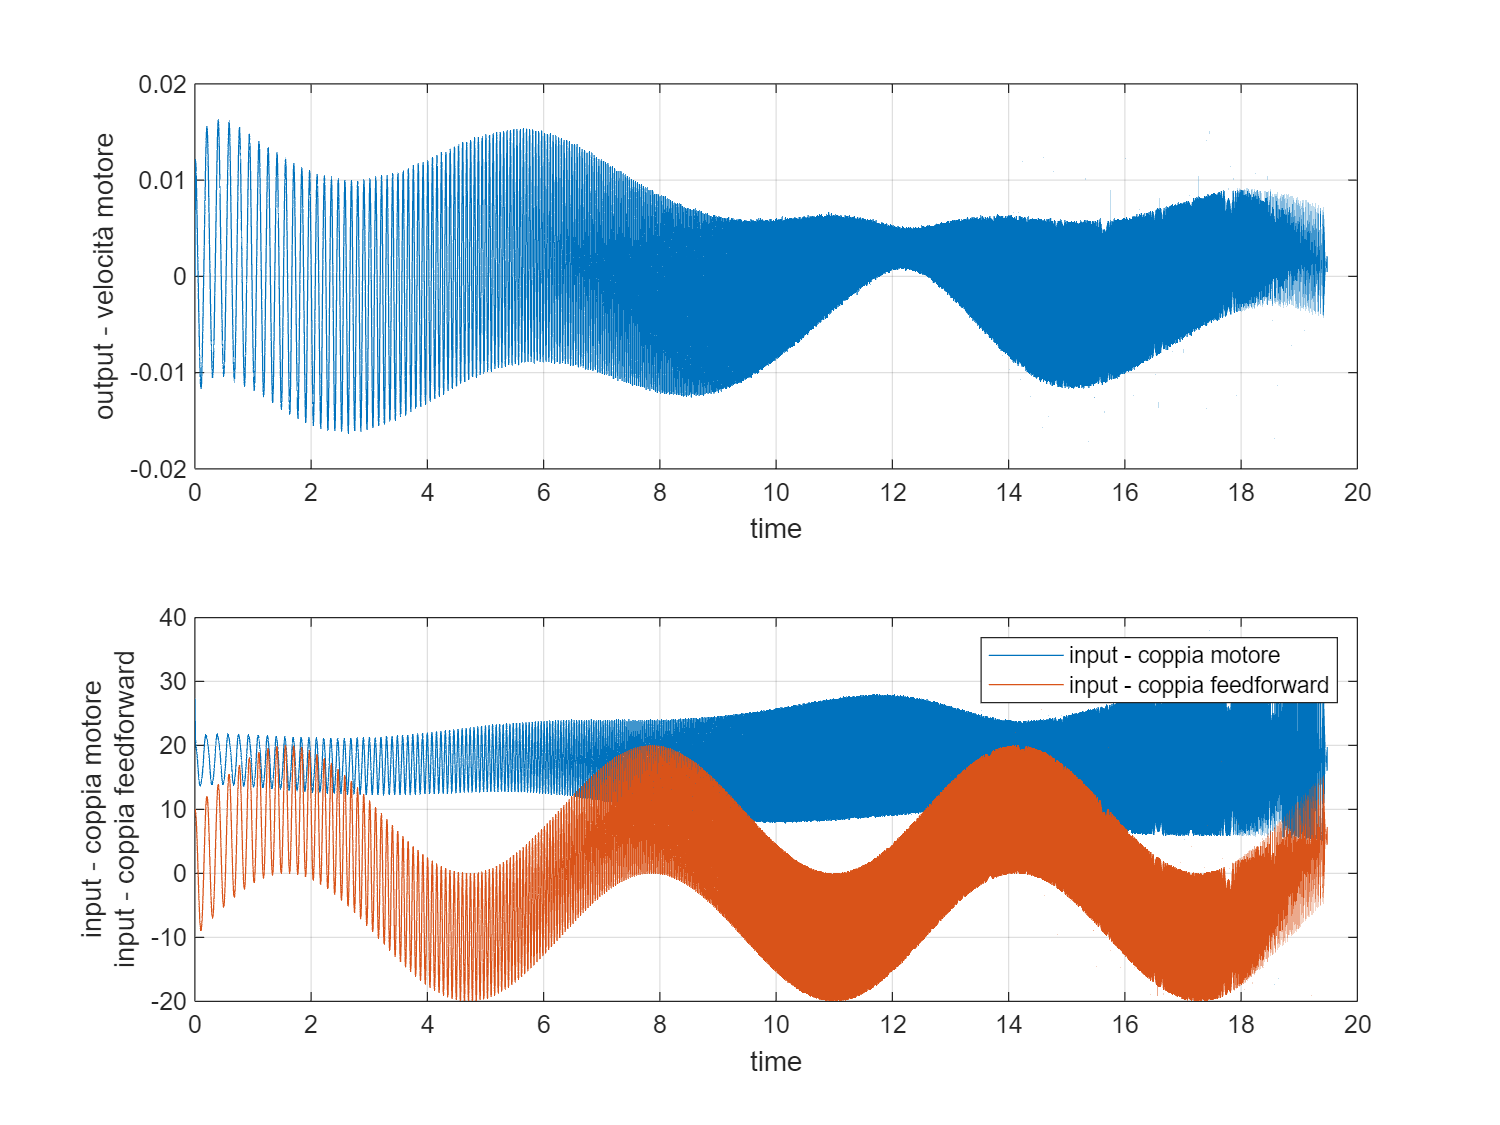


figure
subplot(2,1,1)
plot(t,joint_velocity)
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action,t,control_action_ffw)
xlabel('time')
ylabel({'input - coppia motore','input - coppia feedforward'})
legend({'input - coppia motore','input - coppia feedforward'})
grid on

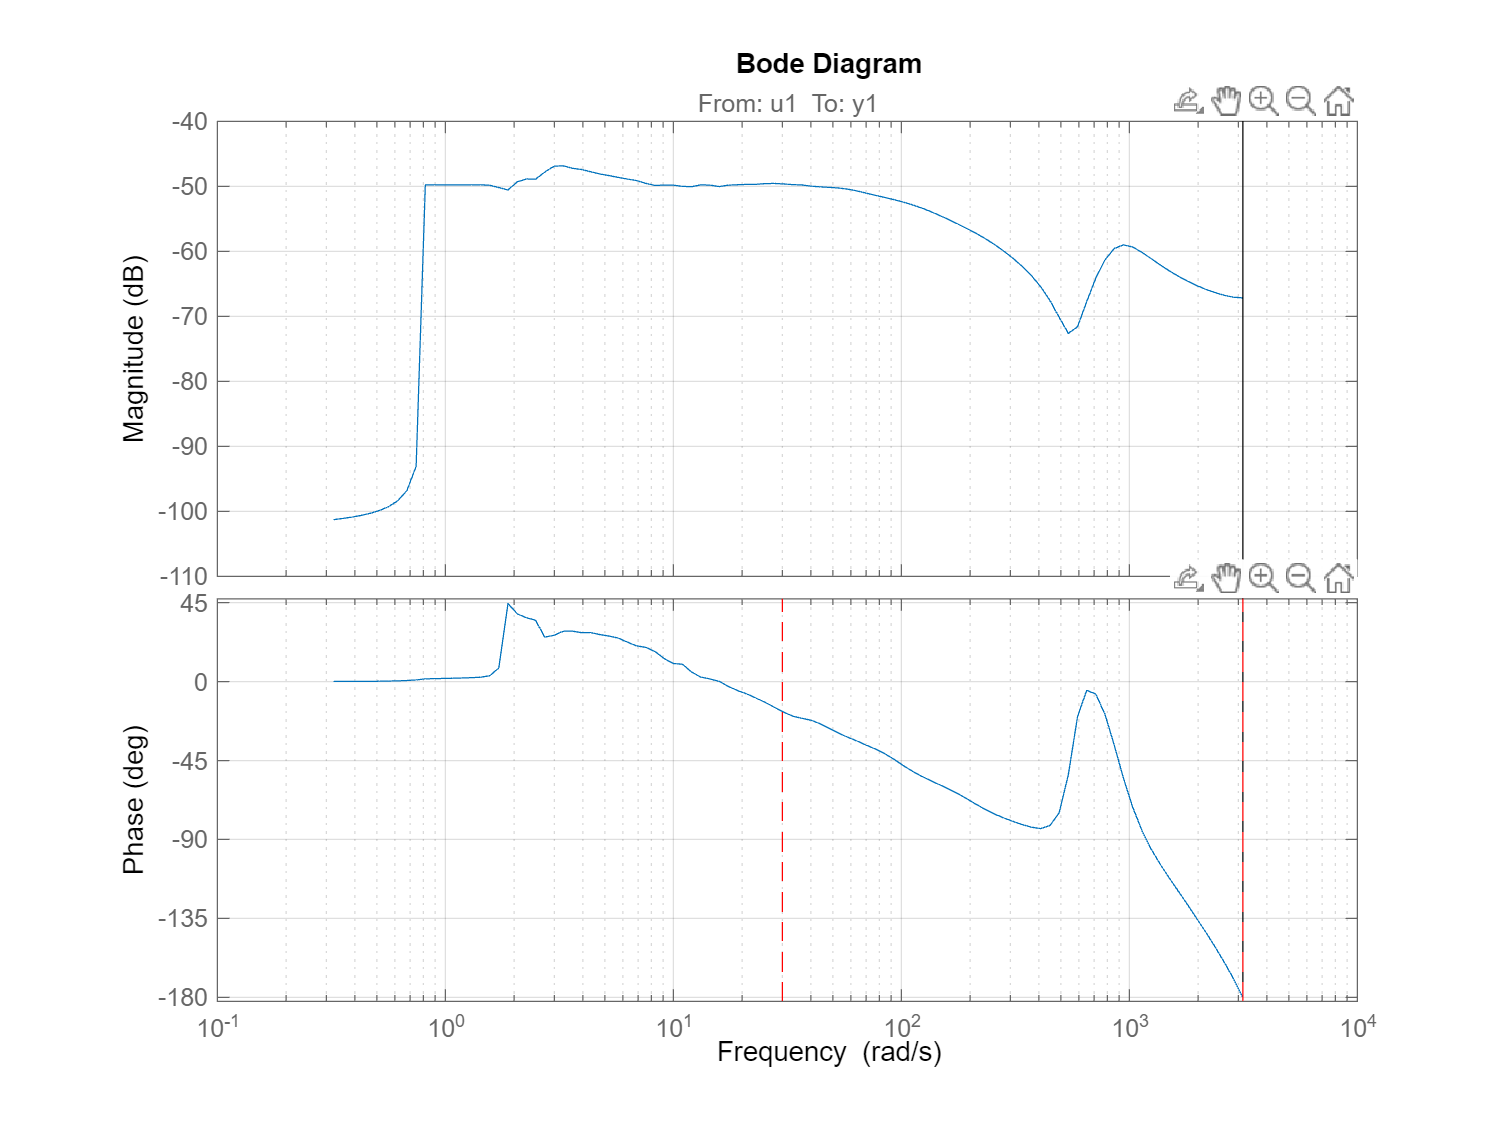



identification=iddata(joint_velocity,control_action,Tc);

freq_resp_ident = spafdr(identification);
figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on
hold on
plot(w0*[1 1],ylim,'--r')
plot(w1*[1 1],ylim,'--r')
hold off
grid on

è da qui in poi si prosegue come gli altri script...